# `Bloch's law analysis`

`Francis Carter`

`LAST UPDATE: 23/03/2020  by Francis`

## `INPUTS:`

%Input the name of the Experiment that you're working on.
INPUTS.Experiment = 'Bloch';

%Input the name of the rats whose data you want to analyse.
INPUTS.Rats = ["ELOP18_R","ELOP18","OP13","ELOP21","ELOP17","OP16"];

%Input the name of the conditions you want to analyse.
INPUTS.Conditions = ["10mW","12.6mW","15.85mW","20mW","31.6mW","50mW"];

%At what TA should we search
INPUTS.RELATIVE = true;
INPUTS.TAMEASURE = 0.5;   %percent time allocation if relative above is False. percent of max if true 

%for plotting 
meanCentered = true;
remove50 = true;

## PLOT BLOCH LINES PER RAT:

cond_idx = 0

cond_idx = 0

cond_idx = 0

cond_idx = 0

cond_idx = 0

cond_idx = 0

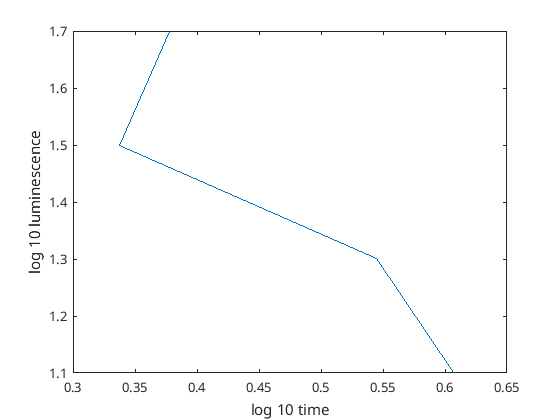

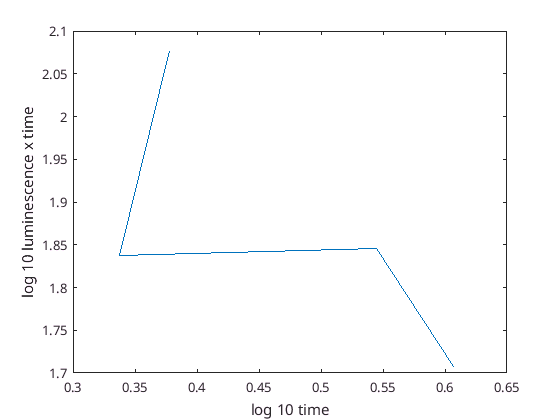

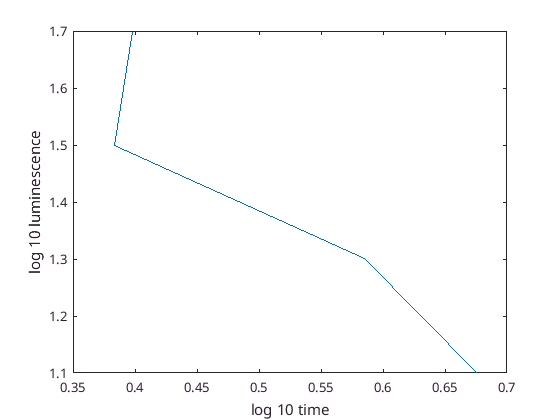

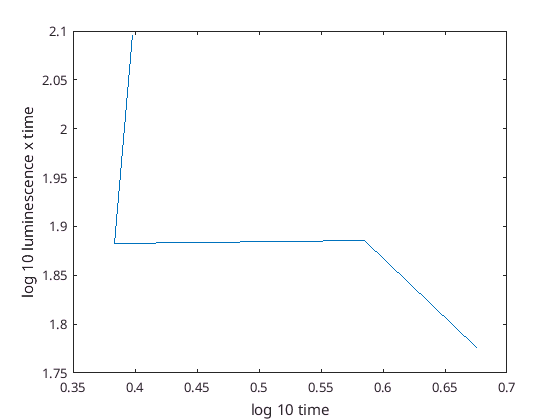

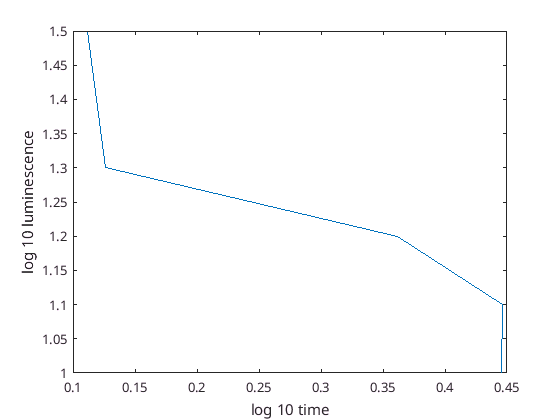

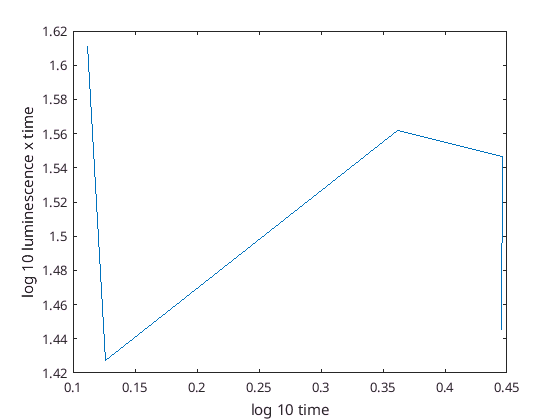

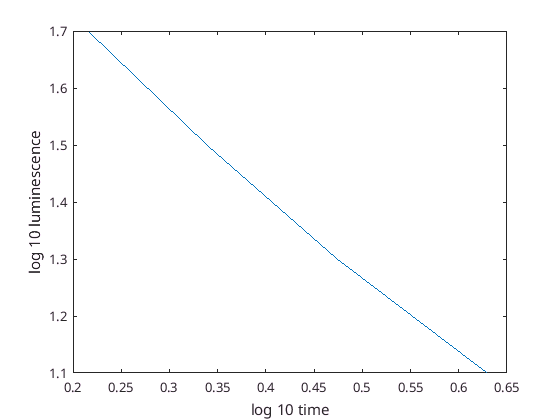

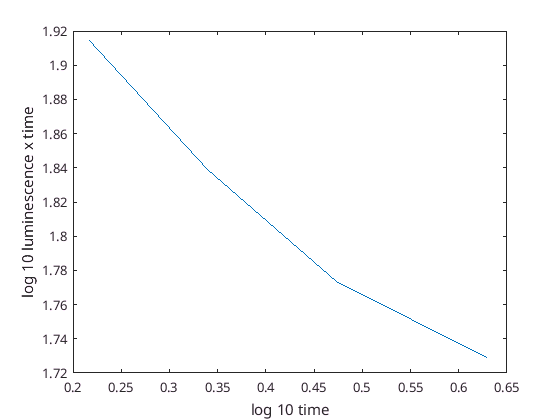

rat_idx = 0;
for Rat = INPUTS.Rats
    rat_idx = rat_idx + 1;
    cond_idx = 0
    for Condition = INPUTS.Conditions 
        cond_idx = cond_idx+1;
        
        try 
            cd(fullfile('/home/francis/Downloads/Bloch/', char(Rat), char(Condition), 'Curve_Fitting'));            
        catch
            BLOCH.(char(Rat)).DATA.CONDS(cond_idx,1) = Condition;
            BLOCH.(char(Rat)).DATA.POWERS(cond_idx,1) = str2num(char(erase(Condition,"mW")));
            BLOCH.(char(Rat)).DATA.MEANCOEFF(cond_idx,:) = nan;
            BLOCH.(char(Rat)).DATA.PDCriterion(cond_idx,1) = nan;
            continue
        end
            
        load(strcat('Data_', Rat,'_',Condition, '.mat'));
        BLOCH.(char(Rat)).DATA.CONDS(cond_idx,1) = Condition;
        BLOCH.(char(Rat)).DATA.POWERS(cond_idx,1) = str2num(char(erase(Condition,"mW")));
        BLOCH.(char(Rat)).DATA.MEANCOEFF(cond_idx,1:4) = DATA.CURVE_FITTING.SECOND_ROUND.Mean_Coefficients;
        
        coef = BLOCH.(char(Rat)).DATA.MEANCOEFF(cond_idx,:);
        if INPUTS.RELATIVE
            height = INPUTS.TAMEASURE * (coef(1)-coef(4)) + coef(4);
        else
            height = INPUTS.TAMEASURE;
        end
        ff = @(x) (coef(4) + (coef(1)-coef(4)) * (1/(1+exp(-coef(2)*(x-coef(3)))))) - height;
        BLOCH.(char(Rat)).DATA.PDCriterion(cond_idx,1) = fzero(ff,0);        
       
    end
    
    if INPUTS.RELATIVE
        mkdir(fullfile('/home/francis/Downloads/Bloch/', char(strcat("Analysis_rel_",num2str(INPUTS.TAMEASURE))),char(Rat)));
        cd(fullfile('/home/francis/Downloads/Bloch/', char(strcat('Analysis_rel_',num2str(INPUTS.TAMEASURE))),char(Rat)));
    else
        mkdir(fullfile('/home/francis/Downloads/Bloch/',char(strcat("Analysis_",num2str(INPUTS.TAMEASURE))),char(Rat)));
        cd(fullfile('/home/francis/Downloads/Bloch/',char(strcat('Analysis_',num2str(INPUTS.TAMEASURE))),char(Rat)));
    end
    
    BLOCH.(char(Rat)).DATA.Quanta(:,1) = log10(BLOCH.(char(Rat)).DATA.POWERS') + BLOCH.(char(Rat)).DATA.PDCriterion(:,1)';
    BLOCH.ALL.DATA.QUANTA(:,rat_idx) = BLOCH.(char(Rat)).DATA.Quanta(:,1);
    BLOCH.ALL.DATA.PDCriterion(:,rat_idx) = BLOCH.(char(Rat)).DATA.PDCriterion(:,1);
    BLOCH.ALL.DATA.POWER(:,rat_idx) = BLOCH.(char(Rat)).DATA.POWERS(:,1);
    BLOCH.ALL.DATA.RATS(rat_idx) = Rat;
    %BLOCH.(char(Rat)).DATA.Quantal(:,1) = log10(BLOCH.(char(Rat)).DATA.POWERS') .* 10.^(BLOCH.(char(Rat)).DATA.PDCriterion(:,1)');
    
    figure;
    x = BLOCH.(char(Rat)).DATA.PDCriterion(:,1)';
    y = log10(BLOCH.(char(Rat)).DATA.POWERS');
    p = plot( x(~isnan(x)),y(~isnan(x)) );
    xlabel('log 10 time');
    ylabel('log 10 luminescence');
    saveas(gcf,'Bloch1.png');
    
    figure;
    x = BLOCH.(char(Rat)).DATA.PDCriterion(:,1)';
    y = BLOCH.(char(Rat)).DATA.Quanta';
    p = plot( x(~isnan(x)),y(~isnan(x)) );
    xlabel('log 10 time');
    ylabel('log 10 luminescence x time');
    saveas(gcf,'Bloch2.png');
    
end

## COMBINING RATS AND PLOTTING:

cd ..

X = BLOCH.ALL.DATA.PDCriterion;
Y = BLOCH.ALL.DATA.POWER;
Y2 = BLOCH.ALL.DATA.QUANTA;
if remove50  %remove 50mW
    X = X(1:end-1, :);
    Y = Y(1:end-1, :);
    Y2 = Y2(1:end-1, :);
end

figure(1)
figure(2)
x = [];
y = [];
y2 = [];
slopes = [];
slopes2 = [];
Legend = cell(length(BLOCH.ALL.DATA.RATS)+1, 1)

Legend = 7×1 cell array
    []
    []
    []
    []
    []
    []
    []


for col = 1:length(BLOCH.ALL.DATA.RATS)
    xCol = X(:,col);
    yCol = log10(Y(:,col));
    y2Col = log10(Y2(:,col));
    if meanCentered
        xColGood = xCol(~isnan(xCol)) - mean(xCol(~isnan(xCol)));
        yColGood = yCol(~isnan(xCol)) - mean(yCol(~isnan(xCol)));
        y2ColGood = y2Col(~isnan(xCol)) - mean(y2Col(~isnan(xCol)));
    else
        xColGood = xCol(~isnan(xCol));
        yColGood = yCol(~isnan(xCol));
        y2ColGood = y2Col(~isnan(xCol));
    end
    x = [x;xColGood];
    y = [y;yColGood];
    y2 = [y2;y2ColGood];
    figure(1)
    plot(xColGood, yColGood);
    Legend{col} = char(INPUTS.Rats(col));
    hold on
    figure(2)
    plot(xColGood, y2ColGood);
    Legend{col} = char(INPUTS.Rats(col));
    hold on
    
    %regression
    xReg = [ones(length(xColGood),1), xColGood];
    slopes(1:2, col) = xReg \ yColGood;
    slopes2(1:2, col) = xReg \ y2ColGood;
end
xFit = [min(x), max(x)];
ySlope = mean(slopes(2,:)) * xFit + mean(slopes(1,:));
figure(1)
plot(xFit,ySlope, 'Color', [.5 .5 .5], 'LineWidth', 2)
Legend{length(Legend)} = char(strcat('Regression line slope = ', char(num2str(mean(slopes(2,:))))));
legend(Legend)
xlabel('log time (mean-centered)');
ylabel('log 10 luminescence (mean-centered)');
saveas(gcf,'BlochOverall1.png');
[STATS.POWER.h,STATS.POWER.p,STATS.POWER.ci,STATS.POWER.stats] = ttest(slopes(2,:)+1)

STATS = struct with fields:
    POWER: [1×1 struct]


STATS = struct with fields:
    POWER: [1×1 struct]


STATS = struct with fields:
    POWER: [1×1 struct]


STATS = struct with fields:
    POWER: [1×1 struct]


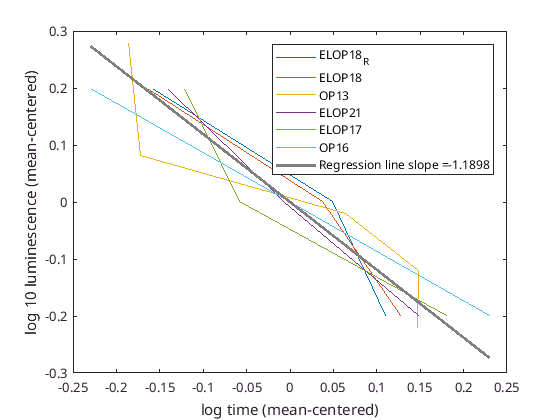

hold off


figure(2)
y2Slope = mean(slopes2(2,:)) * xFit + mean(slopes2(1,:));
plot(xFit,y2Slope, 'Color', [.5 .5 .5], 'LineWidth', 2)
Legend{length(Legend)} = char(strcat('Regression line slope = ', char(num2str(mean(slopes2(2,:))))));
legend(Legend)
xlabel('log time (mean-centered)');
ylabel('log 10 luminescence x time (mean-centered)');
ylim([-0.3 0.3]);
saveas(gcf,'BlochOverall2.png');
[STATS.QUANTA.h,STATS.QUANTA.p,STATS.QUANTA.ci,STATS.QUANTA.stats] = ttest(slopes2(2,:))

STATS = struct with fields:
     POWER: [1×1 struct]
    QUANTA: [1×1 struct]


STATS = struct with fields:
     POWER: [1×1 struct]
    QUANTA: [1×1 struct]


STATS = struct with fields:
     POWER: [1×1 struct]
    QUANTA: [1×1 struct]


STATS = struct with fields:
     POWER: [1×1 struct]
    QUANTA: [1×1 struct]


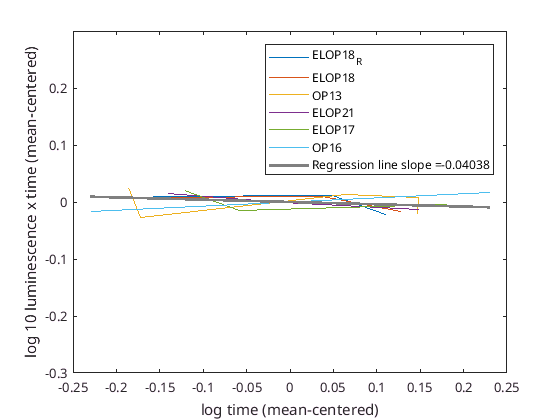

hold off


save('BLOCH')




